## Parametros del programa

model = 2;                                          % Tipo de clasificador (1 -> TreeBagger | 2 -> SVM)
is_video = true;                                   % Indica si el archivo es un video o no (TRUE -> Video | FALSE -> Imagen)
computeAll = false;                                 % Indica si se desea computar de golpe todo el video y guardarlo como archivo de video .avi (TRUE) o verlo frame a frame (FALSE).
video_path = 'C:\Users\Edgar\Downloads\VID_20200113_231621.mp4';     % Nombre del archivo de video de salida (en caso de computeAll == TRUE)
file = 'C:\Users\Edgar\Downloads\VID_20200113_231621.mp4';   % Ruta del archivo a procesor

## Modo test

testing = false;
testFile = 'Short Project\ImageSet\Imagenes\cow_mask.jpg';

## Marcar objeto

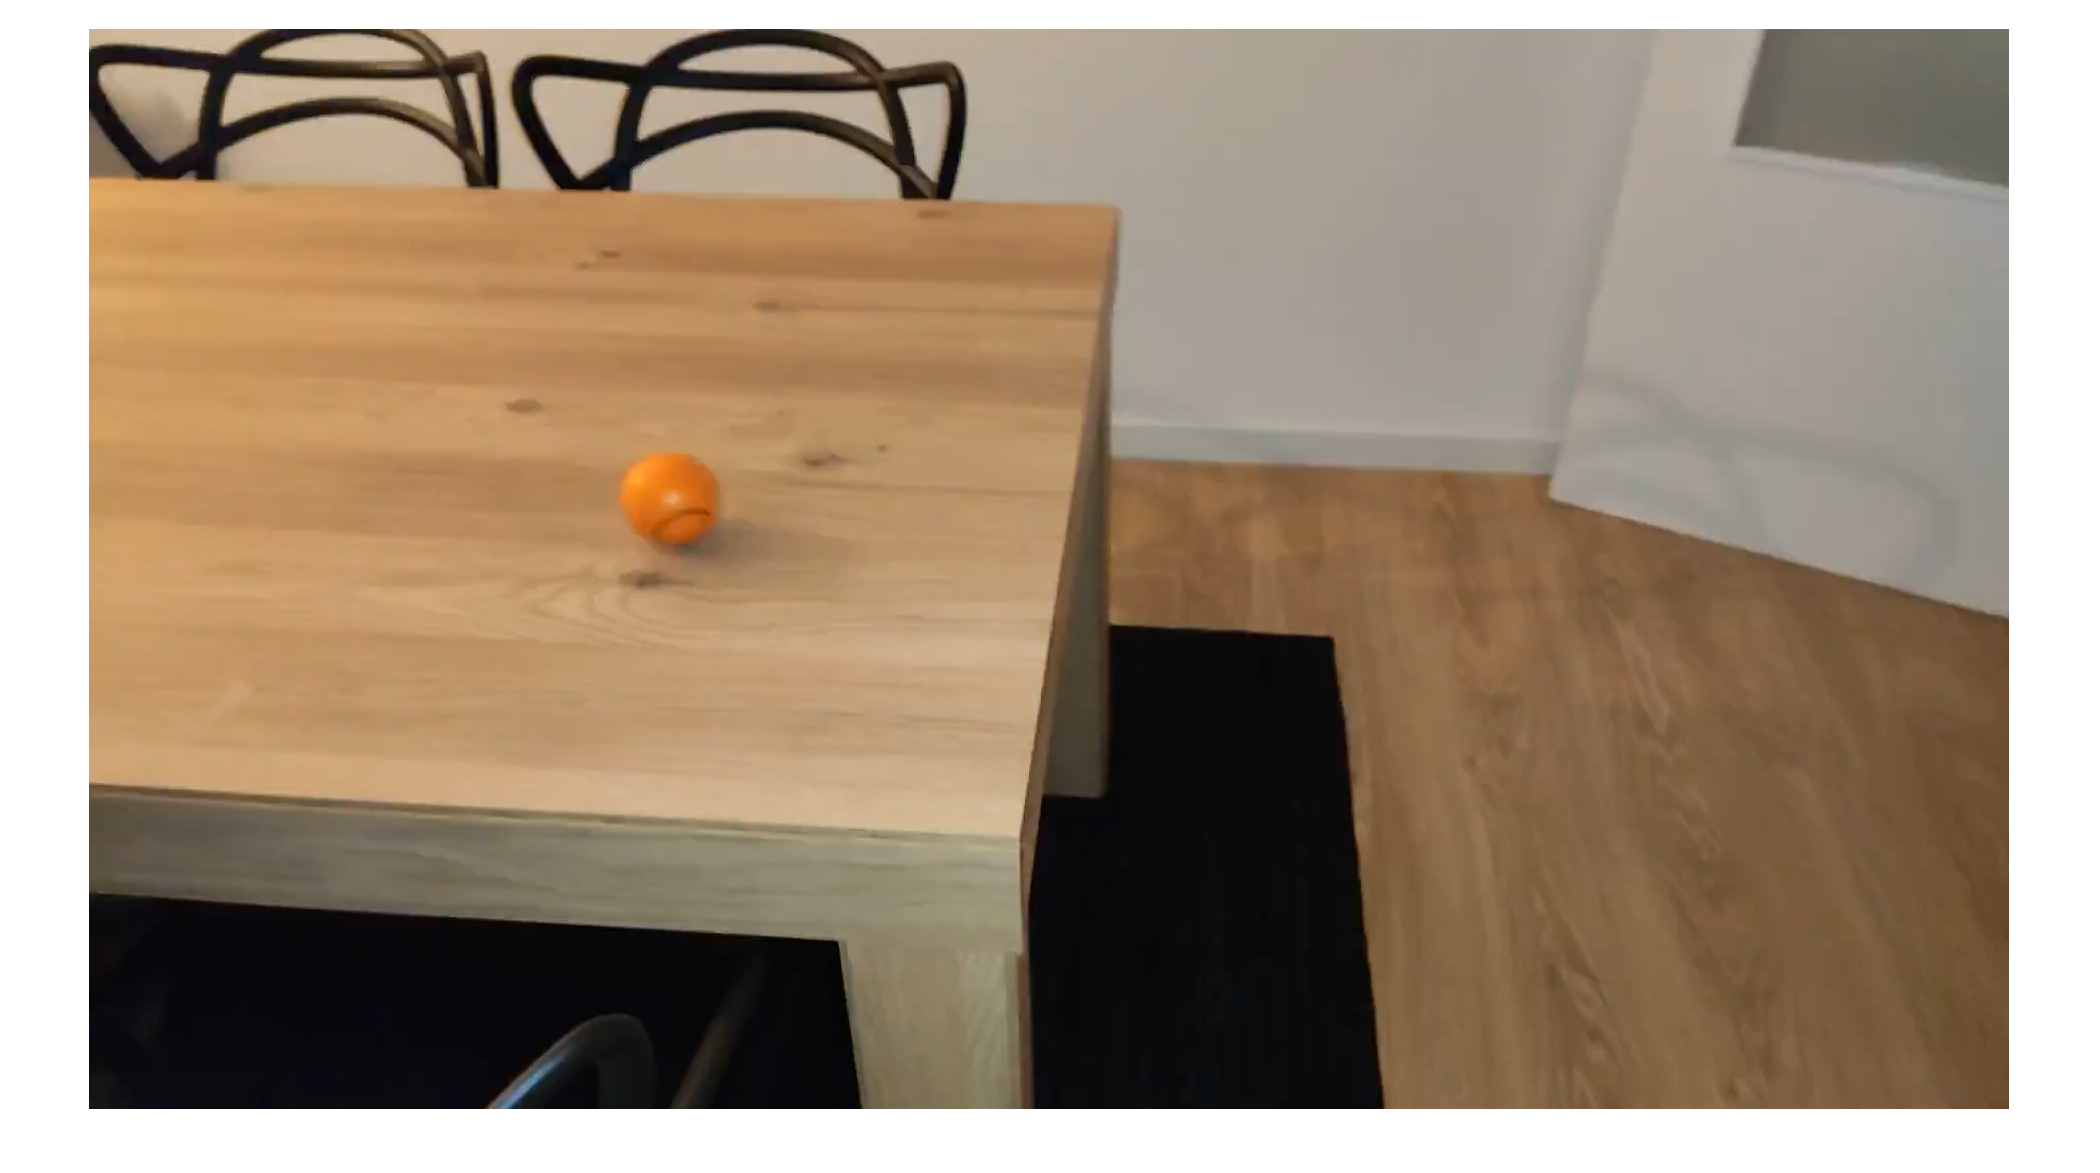

if is_video
    V = VideoReader(file);
    I = V.readFrame;
else 
    I = imread(file);
end

% Entrada del rectangulo
imshow(I);

rect = getrect;

'getrect' requires Image Processing Toolbox.


imshow(I);
hold on;
rectangle('Position',rect,'EdgeColor','r','LineWidth', 3);
hold off;

## Creacion y entrenamiento del predictor

%%% PREPARACION %%%

    % Rectanculo objeto
    x = uint32(rect(1));
    y = uint32(rect(2));
    wx = uint32(rect(3));
    wy = uint32(rect(4));

    % Dimension de la ventana de observacion
    n = 10;     % windows size (rows)
    m = 10;     % windows size (cols)

    % Calculo de dimensiones totales y utiles
    heigth = size(I,1);                         % altura real de la imagen
    width = size(I,2);                          % anchura real de la imagen  
    heigthAdjusted = heigth - mod(heigth, n);   % altura util de la imagen                           
    widthAdjusted = width - mod(width, m);      % anchura alineada al tamano del bloque
    
    % Calculo del tamano de los bloques.
    NumBlocks = heigthAdjusted/n * widthAdjusted/m; % Numero total de bloques a inspeccionar
    
    % Preallocation
    BLOCK_MAP = zeros(heigth,width);       % Mapeo de pixeles a bloques
    BLOCK_MASK= zeros(1,NumBlocks);         % Mascara de si es objeto o no

    % Calculo del mapping pixel - bloque
    colBlocks = heigthAdjusted/n;
    for j = 1:widthAdjusted
        for i = 1:heigthAdjusted
            BLOCK_MAP(i,j) = ceil(i/n) + colBlocks * (ceil(j/m) - 1);
        end
    end
    
    % Calculo de la mascara de bloques (si un bloque es o no objeto).
    for j = x:(x+wx)
        for i = y:(y+wy)
            if BLOCK_MAP(i,j) ~= 0
                BLOCK_MASK(1,BLOCK_MAP(i,j)) = BLOCK_MASK(1,BLOCK_MAP(i,j)) + 1;
            end
        end
    end
    BLOCK_MASK = (BLOCK_MASK > floor(n*m/2))';
    
%% EXTRACCION DE DATOS DE ENTRENAMIENTO %%
    [DATA, ~, ~, ~] = extractFeatures(I, n, m);

%% ENTRENAMIENTO %%
switch model
    case 1
        Model = TreeBagger(100, DATA, BLOCK_MASK);
    case 2
        Model = fitcsvm(DATA,BLOCK_MASK);
end

## Procesamiento de la primera imagen (contorno perfilado)

n = 4;
m = 4;

[DATA, BLOCK_MAP, widthAdjusted, heigthAdjusted] = extractFeatures(I, n, m);
[OBJECT, BB] = getPredictedMask(Model, model, DATA, BLOCK_MAP, widthAdjusted, heigthAdjusted, true, x, wx, y, wy);


OUT = I;

for j = x:(x+wx)
    for i = y:(y+wy)
        if BB(i,j)
            OUT(i,j,:) = [255 0 0];
        end
    end
end

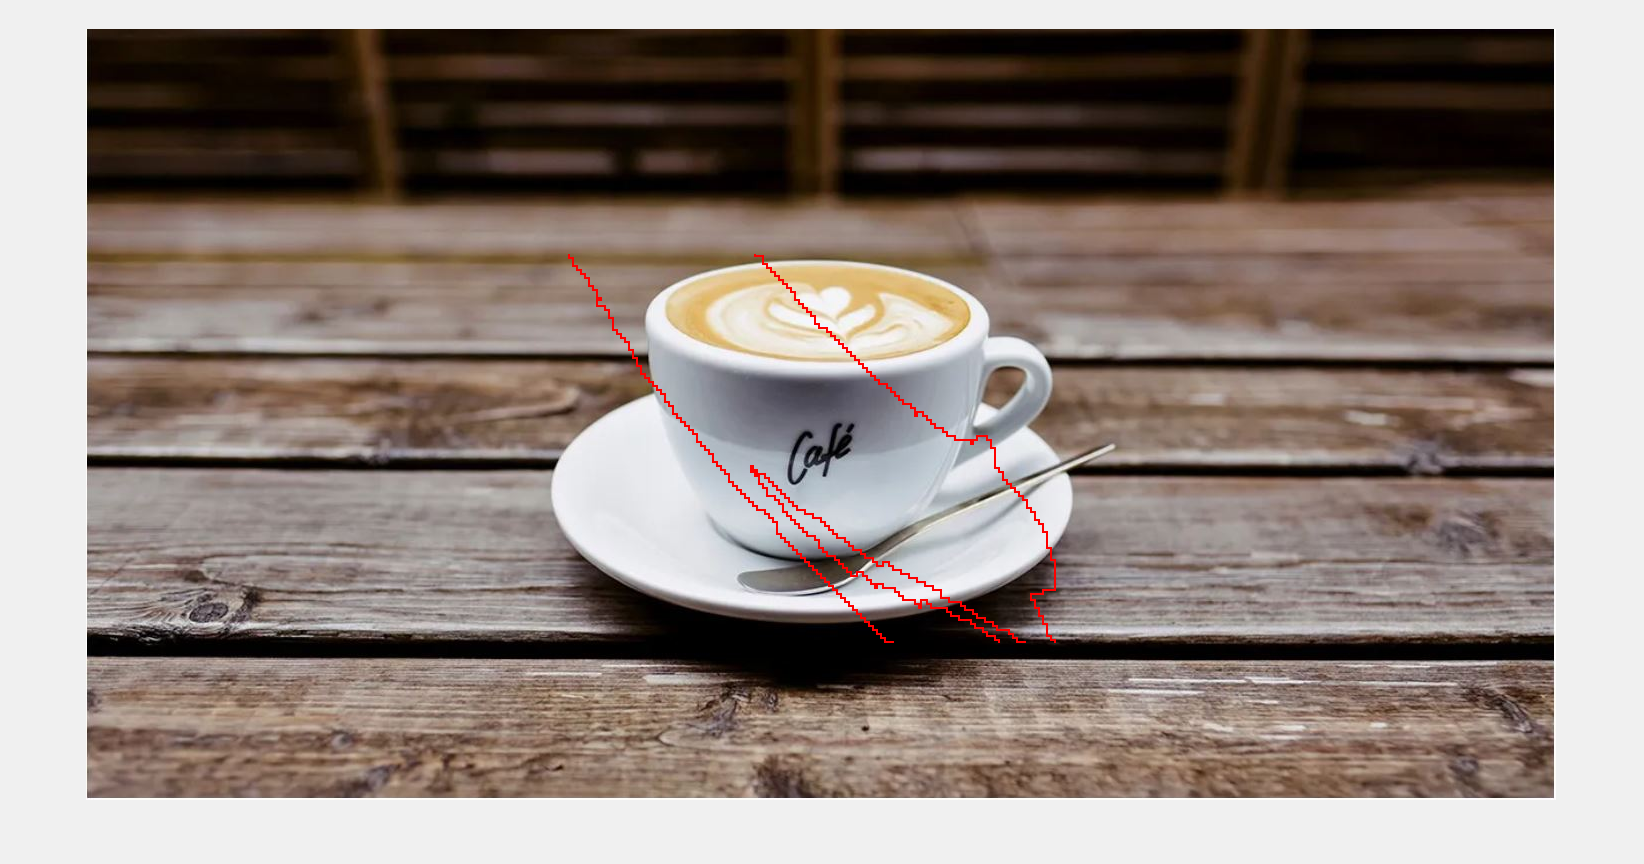

imshow(OUT, []);

## Testing

% Zona del codigo dedicada al testing con segmentaciones generadas manualmente.
% Si deseamos ejecutar esta zona, debemos poner testing = TRUE y dar la ruta a la imagen mascara correspondiente (testFile).

if testing
    MASK = imread(testFile);
    [out, cm] = testResult(OBJECT, MASK);
    imshow(out, []);

    cm = confusionchart(cm, {'No Objeto', 'Objeto'});
    cm.RowSummary = 'row-normalized';
    cm.ColumnSummary = 'column-normalized';

end

## Procesamiento de los siguientes frames

if is_video && computeAll
    
    movie_obj = VideoWriter(video_path);
    open(movie_obj);
    
    while (is_video && hasFrame(V))
        
        % Get new frame
        I = V.readFrame;
        
        % Extract features + predict
        [DATA, BLOCK_MAP, widthAdjusted, heigthAdjusted] = extractFeatures(I, n, m);
        [OBJECT, BB] = getPredictedMask(Model, model, DATA, BLOCK_MAP, widthAdjusted, heigthAdjusted, false);      
        
        % Draw rectangle onto image
        fh = figure('visible','off');
        imshow(I);
        hold on;
        rectangle('Position',BB,'EdgeColor','r','LineWidth', 3);
        hold off;
        
        % Save frame
        frm = getframe(fh);                 % get the image + rectangle
        writeVideo(movie_obj, frm.cdata);   % write on video file
    end
    
    close(movie_obj);
    clear;

elseif is_video
    
    % Get new frame
    I = V.readFrame;
    
    % Extract features + predict
    [DATA, BLOCK_MAP, widthAdjusted, heigthAdjusted] = extractFeatures(I, n, m);
    [OBJECT, BB] = getPredictedMask(Model, model, DATA, BLOCK_MAP, widthAdjusted, heigthAdjusted, false);
    
    % Draw and show rectangle and image
    imshow(I);
    hold on;
    rectangle('Position',BB,'EdgeColor','r','LineWidth', 3);
    hold off;
    
end

%clear;